# Prognostic Health Management

**Name**: 

Kwak, Jin/21900031

Kim, Sunwoo/22000090

**Date**       :2024.10.05

**Modified**:2024.10.12

# Introduction

In this lab, [](https://www.kamp-ai.kr/aidataDetail?AI_SEARCH=&page=1&DATASET_SEQ=23&EQUIP_SEL=&GUBUN_SEL=C004025&FILE_TYPE_SEL=&WDATE_SEL=CLICK_NUM)[AI dataset for early detection of equipment abnormalities](https://www.kamp-ai.kr/aidataDetail?AI_SEARCH=&page=1&DATASET_SEQ=23&EQUIP_SEL=&GUBUN_SEL=C004025&FILE_TYPE_SEL=&WDATE_SEL=CLICK_NUM) is used to develop a machine learning model for coil defect diagnosis(Hot-Air Process Equipment)

### **Process Description**

Hot-Air Drying Process:

    - Ensures that the film and protective agents adhere stably to the metal surface after plating

    - Completely dries moisture from the product surface.

    - Used in various fields(e.g. electronic component coating, automotive paint processes, and ceramic processes)

    - **Process Defects**

        - High power consumption using coil $\rightarrow$Overheating, Irregular temperature transmission $\rightarrow$Poor product quality/Equipment Fault

        - Coil fault may cause issues with the cooling motor $\rightarrow$ Vibration patterns changes.

The goal is to identify these changes to diagnose the issues early on and prevent equipment failure.

## Goal of the Project

Two separate, distinguishable goals.

- Development of a Machine Learning model for coil defect diagnosis using data in Hot-Air process equipment

- Analysis of the Remaining Useful Life trend and establish degradation model

## Specific Goals

1.1) Achieve detection(Normal/Error) accuracy up to 90% 

1.2) Ensure the model performance with Feature Reduction and analyze the feature reduction

2.1) 80% < Probability of Predicted RUL within αbound after Train-Test Breakpoint

## Dataset

Dataset name: [AI dataset for early detection of equipment abnormalities](https://www.kamp-ai.kr/aidataDetail?AI_SEARCH=&page=1&DATASET_SEQ=23&EQUIP_SEL=&GUBUN_SEL=C004025&FILE_TYPE_SEL=&WDATE_SEL=CLICK_NUM)

Data Measurement:

- PLC data(Sampling Period: 5[sec])

- Sound data

Data Categories:

- Numerical data from PLC 

- Sound data:

- Error Lot list

## **Goal of the Project**

Two main goals of the project are introduced in this project. The dataset is originally used for classification. Authors will prepare for a **ML model for fault classification** and **Fault Diagnosis Model(Remaining Useful Life Estimation Model)**

- Development of a Machine Learning model for coil defect diagnosis using data in Hot-Air process equipment

- Analysis of the Remaining Useful Life trend and establish **degradation model**

## **Expected Outcome**

**Before: **Difficulty on immediate problem check of coil defects on-site on real-time base

**After: **Quickly respond to equipment fault $\rightarrow$Equipment management, Increase in productivity.

## Schedule

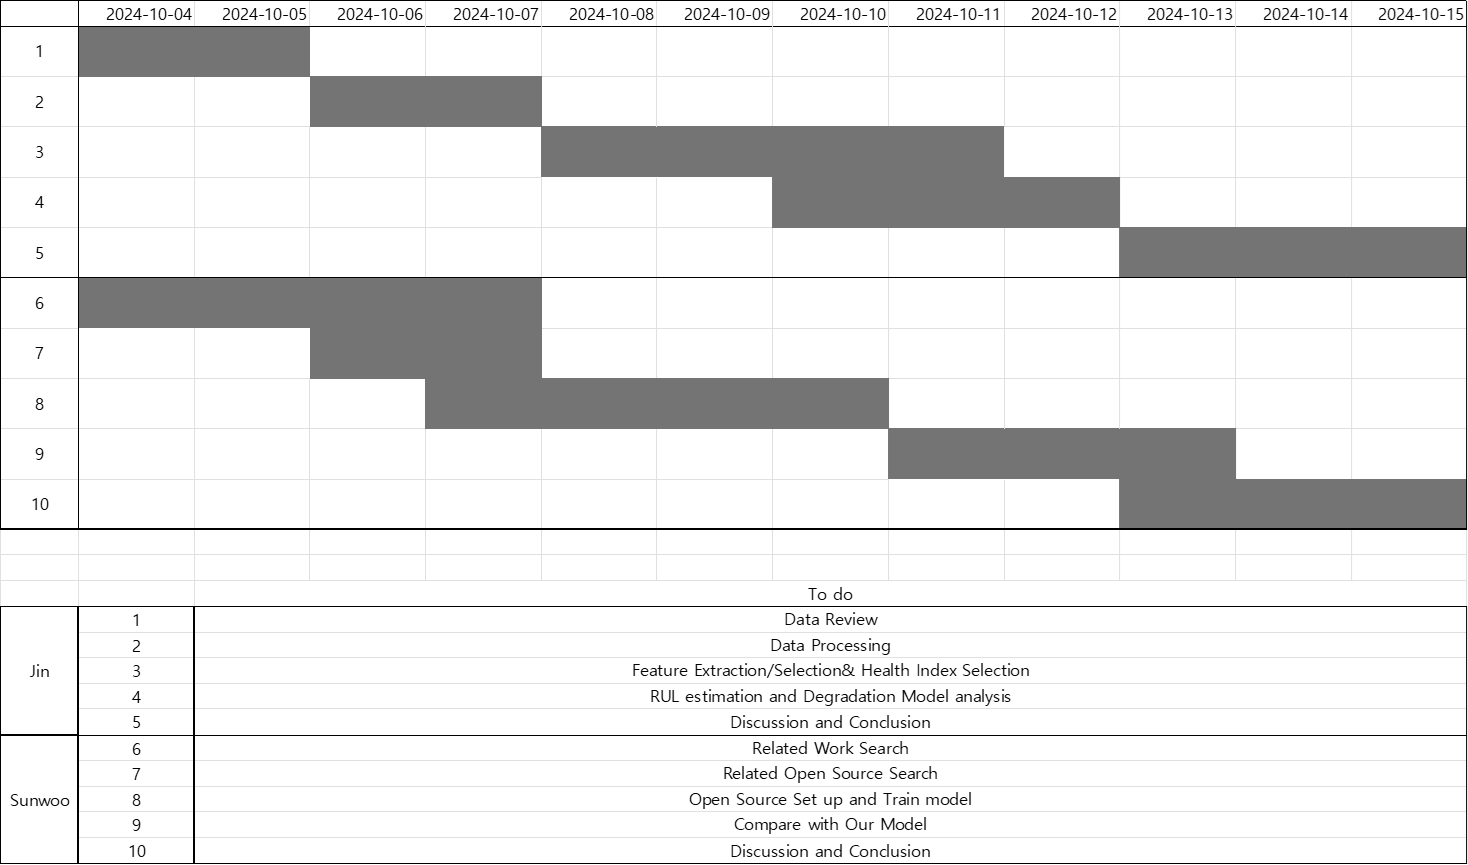

clc; clear all;
addpath("data\FAN_sound_error\");
addpath("data\FAN_sound_OK\")   ;
addpath("data\5공정_180sec\")   ;

**Import Sound Data **

N_sound_error = 13                               ;
N_sound_normal= 170                              ;
error_sound_filename  = "FAN_sound_error_0%d.wav";
normal_sound_filename = "FAN_sound_0%d.wav"      ;
for idx = 1:9
    filename = sprintf(error_sound_filename,idx) ;
    [y,Fs] = audioread(filename)                 ;
    sound_error{idx,1} = y                       ;
    sound_error{idx,2} = Fs                      ;
    filename = sprintf(normal_sound_filename,idx);
    [y,Fs] = audioread(filename)                 ;
    sound_normal{idx,1} = y                      ;
    sound_normal{idx,2} = Fs                     ;
end
error_sound_filename = "FAN_sound_error_%d.wav"  ;
normal_sound_filename= "FAN_sound_%d.wav"        ;
for idx = 10:13
    filename = sprintf(error_sound_filename,idx) ;
    [y,Fs] = audioread(filename)                 ;
    sound_error{idx,1} = y                       ;
    sound_error{idx,2} = Fs                      ;
end
for idx = 10:N_sound_normal
    filename = sprintf(normal_sound_filename,idx);
    [y,Fs] = audioread(filename)                 ;
    sound_normal{idx,1} = y                      ;
    sound_normal{idx,2} = Fs                     ;
end

**Import PLC data**

Unfortunately, the time-series data is not strictly real-time, in which means that this data is collected every 5 seconds approximately.

day   = [6:10,13:17,23,24,27:30,1,5:8,12:15,18:22,25:27];
month = [9*ones(1,16),10*ones(1,17)];
dates = datetime(2021,month,day,'Format','uuuu.MM.dd');
txt_form = "kemp-abh-sensor-%s.csv";
for idx = 1:length(day)
    file_name    = sprintf(txt_form,dates(idx));
    data_temp    = readmatrix(file_name) ; 
    plc_data{idx}= data_temp(:,[1,2,4,5]); 
end


**Data Enumeration**

Cell data will be in time-series and each features are grouped by a struct.

% Enumerations
IDX      = 1  ;
PROCESS  = 2  ;
TEMP     = 3  ;
CURRENT  = 4  ;
CLASS    = 5  ;
% For cell data
RAW_DATA = 1  ;
MAX_FREQ = 2  ;
FEAT     = 3  ;


**The sound data** is very similar to the vibration data as it has amplitude and frequency. Time and frequency features are to be extracted for the data analysis.

However, the sound data is subdivided into normal/error which means this should be only used as classification not RUL. Only possible if the sound data can be collected on real-time

for idx = 1 : N_sound_error
    sound_error{idx,3} = get_features(sound_error{idx,1});
end
for idx = 1 : N_sound_normal
    sound_normal{idx,3} = get_features(sound_normal{idx,1});
end

Compare time-domain sound data of normal/error

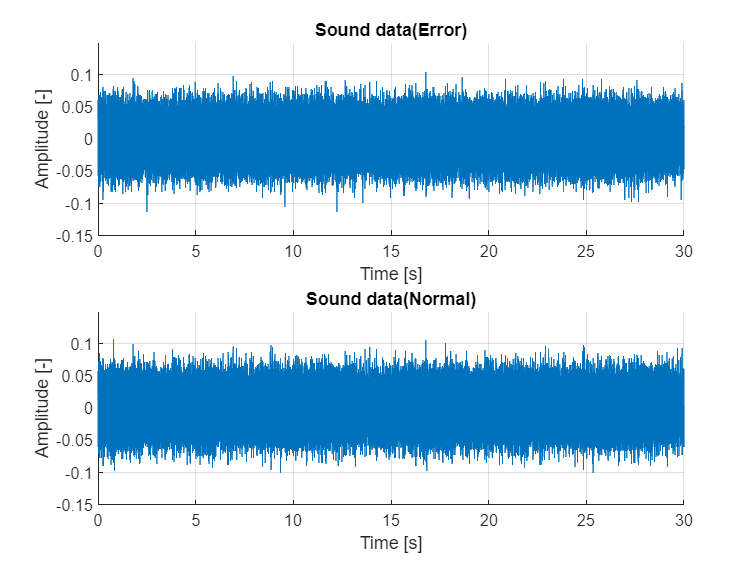

idx = 13;

ex_sound_error = sound_error {idx,RAW_DATA}(:,1);
ex_sound_normal= sound_normal{idx,RAW_DATA}(:,1);
time = 0:1/sound_error{idx,MAX_FREQ}:(length(ex_sound_error)-1)/Fs;

figure;
subplot(2,1,1); hold on;
title('Sound data(Error)','FontWeight','bold');
plot(time, ex_sound_error);grid on;
xlabel('Time [s]'); ylabel("Amplitude [-]");
time = 0:1/sound_normal{idx,MAX_FREQ}:(length(ex_sound_normal)-1)/Fs;
ylim([-0.15 0.15]);
subplot(2,1,2); hold on;
title('Sound data(Normal)','FontWeight','bold');
plot(time, ex_sound_normal); grid on           ;
xlabel('Time [s]'); ylabel("Amplitude [-]")    ;
ylim([-0.15 0.15]);

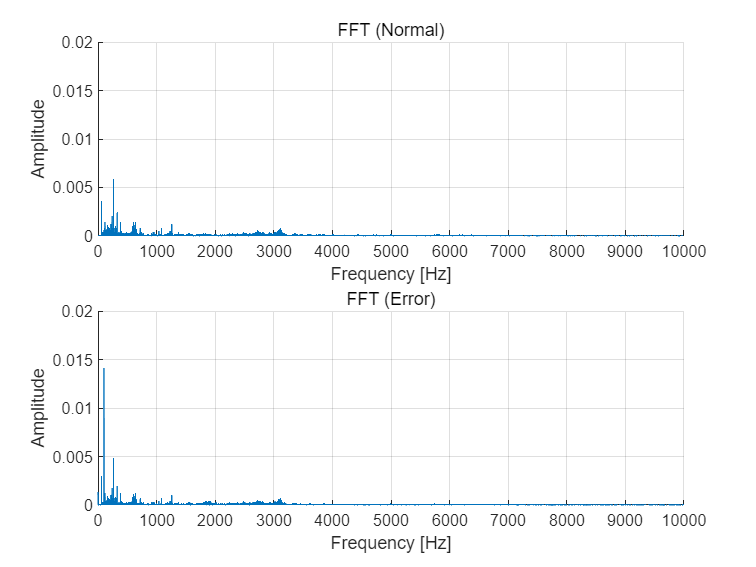

Fs = 44100;  %Hz
figure;
[freq, amp_normal] = get_fft(ex_sound_normal,Fs);
[freq, amp_error]  = get_fft(ex_sound_error,Fs);
figure;
subplot(2,1,1); hold on; grid on;
plot(freq,amp_normal); xlabel('Frequency [Hz]'); ylabel('Amplitude');
title('FFT (Normal)');ylim([0 0.02]); xlim([0 1e4]);
subplot(2,1,2); hold on; grid on;
plot(freq,amp_error); xlabel('Frequency [Hz]'); ylabel('Amplitude');
title('FFT (Error)');ylim([0 0.02]); xlim([0 1e4]);

To further illustrate the frequency features of normal/error data, `get_freq_features()` function is used.

normal_frequency_features = get_freq_features(amp_normal,Fs)

normal_frequency_features = 1×3 table
       max_amplitude       frequency_of_max_amplitude         DC_value      
    ___________________    __________________________    ___________________

    0.00583483055408493         518.599216025373         3.4779524975556e-07


error_frequency_features  = get_freq_features(amp_error,Fs)

error_frequency_features = 1×3 table
      max_amplitude       frequency_of_max_amplitude         DC_value      
    __________________    __________________________    ___________________

    0.0141144665900067         199.999697657298         0.00129010997684206


Each time features, frequency features are collected and averaged. They are plotted as below

First few sample data time features plot. This shows that error sound is very random and shows inconsistent values of all features.

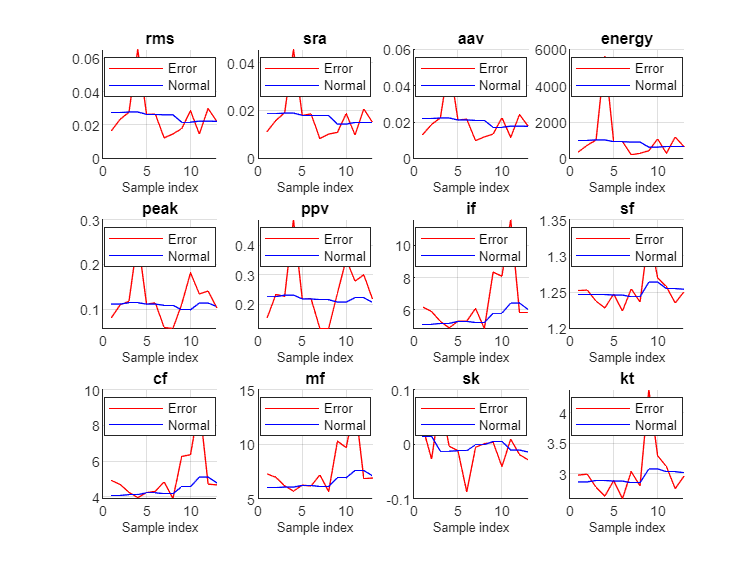

feature_names =["rms" "sra" "aav" "energy" "peak" "ppv" "if" "sf" "cf" "mf" "sk" "kt" "fft"];
figure;
for idx = 1:(length(feature_names)-1)
    avg(idx,1) = get_average_feature(sound_error ,feature_names(idx))       ;
    avg(idx,2) = get_average_feature(sound_normal,feature_names(idx))       ;
    error_features(:,idx)= get_all_feature(sound_error ,feature_names(idx)) ;
    normal_features(:,idx)= get_all_feature(sound_normal,feature_names(idx));
    subplot(3,4,idx); hold on; grid on           ;
    plot(error_features(:,idx),'r-')             ; 
    plot(normal_features(1:13,idx),'b-')         ;
    legend('Error','Normal')                     ;
    legend('Location','best')                    ;
    xlabel('Sample index','FontSize',7)          ;
    title(feature_names(idx),'FontWeight','bold');
end

# Data Preprocessing

## error data processing

% temperture / current 값에 대해서 error 별로 feature 뽑기
% PLC time-domain analysis

N_plc = 33;
Fs = 1.0 /5.0;
for idx = 1 : N_plc
    temp = plc_data {idx};
    plc_current{idx,1}  = temp(:,3);
    plc_current{idx,2}  = Fs;
    plc_current{idx,3}  = get_features(plc_current{idx,1});
    plc_temperature{idx,1}= temp(:,4);
    plc_temperature{idx,2}= Fs;
    plc_temperature{idx,3}= get_features(plc_temperature{idx,1});
end


error_list = readmatrix("Error Lot list.csv");
error_list = error_list(2:end,2:end);
if exist("var_names")
    clear var_names;
end
if exist("var_types")
    clear var_types;
end
for idx =1:length(error_list(1,:))
    var_names(idx) = sprintf("Error%d",idx);
end
var_names  = ["datetime" var_names];
error_names= var_names(2:end);

var_types(1,1:11) = "double";

var_types = ["datetime" var_types];
size_error_list =size(error_list);
size_error_list(2) = size_error_list(2)+1;
error_table= table('Size',size_error_list,'VariableTypes',var_types,'VariableNames',var_names);
error_table.datetime = dates';
for row = 1:length(error_list(:,1))
    for col = 1:length(error_list(1,:))
        if isnan(error_list(row,col))
            error_list(row,col) = 0;
        end
    end
end
error_table(:,2:end) = array2table(error_list);

% Sort by error
for row = 1:length(plc_data)
    temp_plc_data      = plc_data{row};
    temp_plc_data(:,5) = 0;
    for col= 1:length(error_list(1,:))
        if error_list(row,col) ~= 0
            indices = find(temp_plc_data(:,2) == error_list(row,col));
            temp_plc_data(indices,5) = col;
        end
    end
    plc_data{row} = temp_plc_data;
end


# Feature extraction

train data 와 test data 나누기

rng(0);
cv = cvpartition(length(day), 'Holdout', 0.2);
test_idx = cv.test;
test_idx(16,1) = 0;
cnt_test = 1;
cnt_train= 1;
% Each cell is test/train dataset.
% Each column represents number of process, current or temperature, and
% classification respectively
for idx = 1:length(day)
    if test_idx(idx)
        test_current{cnt_test}     = plc_data{idx}(:,[PROCESS CURRENT CLASS]);
        test_temperature{cnt_test} = plc_data{idx}(:,[PROCESS TEMP CLASS]);
        cnt_test = cnt_test + 1;
    else
        train_current{cnt_train}     = plc_data{idx}(:,[PROCESS CURRENT CLASS]);
        train_temperature{cnt_train} = plc_data{idx}(:,[PROCESS TEMP CLASS]);
        cnt_train= cnt_train + 1;
    end
end

train & test featrue

% TODO Get features of each process

for idx_day = 1:length(train_current)
    train_current_day = train_current{idx_day};
    train_temperature_day = train_temperature{idx_day};
    process = 1;
    start_idx = 1;

    for idx_time = 1:length(train_current_day)
        if train_current_day(idx_time,1) ~= process  
            end_idx = idx_time - 1;
            idx_feature = process + (43 * (idx_day - 1));
            train_current_feature(idx_feature) = get_features_error(train_current_day(start_idx:end_idx,2), train_current_day(start_idx:end_idx,3)) ;
            train_temperature_feature(idx_feature) = get_features_error(train_temperature_day(start_idx:end_idx,2), train_temperature_day(start_idx:end_idx,3)) ;
            process = train_current_day(idx_time,1);
            start_idx = idx_time ;
        end
        
        if train_current_day(idx_time,1) == 43
            end_idx = length(train_current_day);
            idx_feature = process + (43 * (idx_day - 1));
            train_current_feature(idx_feature) = get_features_error(train_current_day(start_idx:end_idx,2), train_current_day(start_idx:end_idx,3)) ;
            train_temperature_feature(idx_feature) = get_features_error(train_temperature_day(start_idx:end_idx,2), train_temperature_day(start_idx:end_idx,3)) ;
        end
        
    end

end

for idx_day = 1:length(test_current)
    test_current_day = test_current{idx_day}(:,[1 2 3]);
    test_temperature_day = test_current{idx_day}(:,[1 2 3]);
    process = 1;
    start_idx = 1;
    
    for idx_time = 1:length(test_current_day)
    
        if test_current_day(idx_time,1) ~= process  
            end_idx = idx_time - 1;
            idx_feature = process + (43 * (idx_day - 1));
            test_current_feature(idx_feature) = get_features_error(test_current_day(start_idx:end_idx,2), test_current_day(start_idx:end_idx,3)) ;
            test_temperature_feature(idx_feature) = get_features_error(test_temperature_day(start_idx:end_idx,2), test_temperature_day(start_idx:end_idx,3)) ;
            process = test_current_day(idx_time,1);
            start_idx = idx_time ;
        end
        
        if test_current_day(idx_time,1) == 43
            end_idx = length(test_current_day);
            idx_feature = process + (43 * (idx_day - 1));
            test_current_feature(idx_feature) = get_features_error(test_current_day(start_idx:end_idx,2), test_current_day(start_idx:end_idx,3)) ;
            test_temperature_feature(idx_feature) = get_features_error(test_temperature_day(start_idx:end_idx,2), test_temperature_day(start_idx:end_idx,3)) ;
        end
        
    end

end

# Feature Selection/Reduction

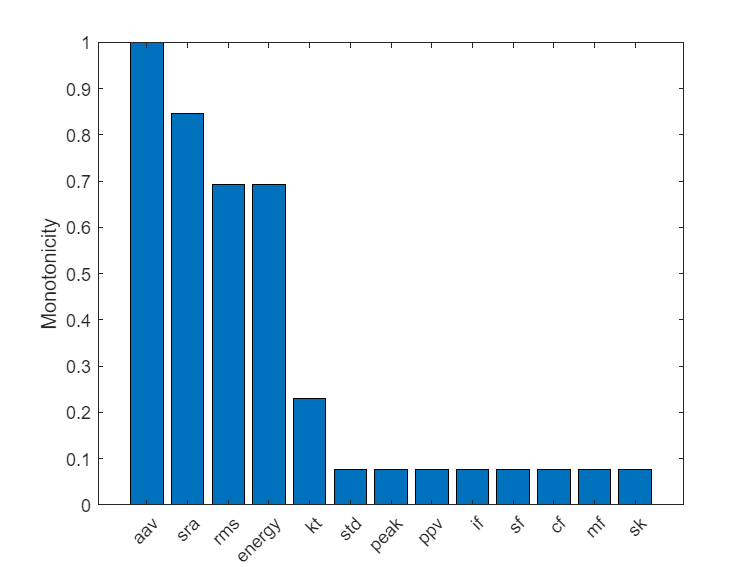

% error 별로 뽑은 feature 들을 feature selectoin 후 featuer reduction을 통해서 feature
% 정하기 temp / current 별로 구분
filed_c = struct2table(train_current_feature(:,1:14));
filed_t = struct2table(train_temperature_feature(:,1:14));
featureTable_current = filed_c(:,1:14);
featureTable_temperature = filed_t(:,1:14);
featureImportance_current = monotonicity(featureTable_current, 'WindowSize', 0);
helperSortedBarPlot(featureImportance_current, 'Monotonicity');

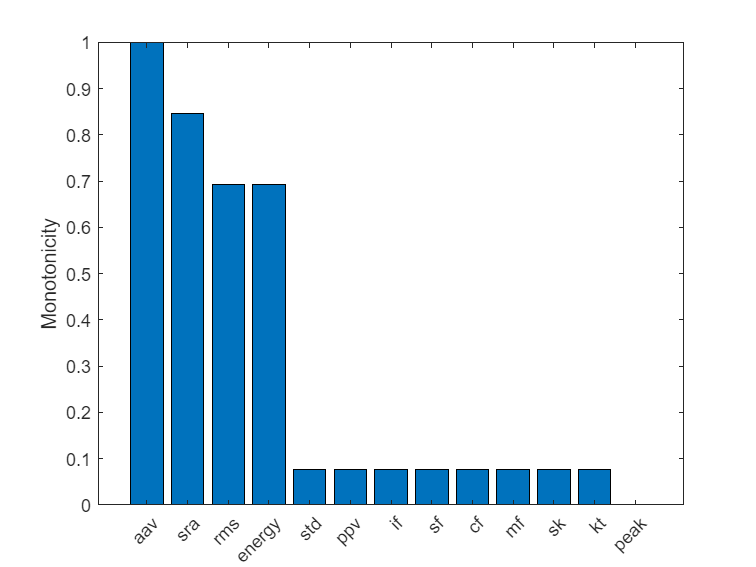

featureImportance_temperature = monotonicity(featureTable_temperature, 'WindowSize', 0);
helperSortedBarPlot(featureImportance_temperature, 'Monotonicity');

Top 4 important features selection

FI_c = featureImportance_current{:,:} > 0.3;
FI_t = featureImportance_temperature{:,:} > 0.3;
trainData_current     = struct2table(train_current_feature);
trainData_temperature = struct2table(train_temperature_feature);
trainDataSelected_current     = trainData_current(:, FI_c)

trainDataSelected_current = 1161×4 table
           std                  rms                 sra                 aav       
    __________________    ________________    ________________    ________________

    0.0649573486439921    1.60577784889442    1.60385717039616              1.6045
    0.0725721753492386     1.6053178466861     1.6029155656007    1.60372222222222
    0.0795466919798394     1.6102681709438    1.60739556561783    1.60835682450544
    0.0747767630063931    1.59928382409127    1.59672932770568    1.59758333333333
    0.0846635732468258    1.60445096182117    1.60119504619413    1.60227777777778
    0.0796197632193672    1.60749462960181    1.60461587658995    1.60557646014015
    0.0697247422550968    1.60452909325793     1.6023158522319    1.60305555555556
    0.0747516195203563    1.61264524252233    1.61012257265678    1.61095999031758
    0.0764865006731028    1.60479817579035    1.60214705054879    1.60302511064791
    0.0900393156502312    1.61906015205115   

trainDataSelected_temperature = trainData_temperature(:, FI_t)

trainDataSelected_temperature = 1161×4 table
          std                 rms                 sra                 aav       
    ________________    ________________    ________________    ________________

     2.7578419218225    71.0012512340581    70.9229806671319    70.9491596423814
    3.37523670765473    70.7986439902536    70.6807377479605    70.7203805042098
    3.27251203974691    71.2146745976064    71.1047907516306    71.1415351571911
    3.42109861797555    70.5330277826499    70.4117583841143     70.452318636118
    3.55123578360386    71.0063218348466    70.8769894842689    70.9199321639123
     3.6943017799344    70.9309762316145    70.7905775008879    70.8373815926842
    3.08679006771316    70.8587939455169    70.7605790620105    70.7933971549531
    3.18785718640472    71.3872060370399     71.283909281837    71.3179713827565
    3.54145217450988    70.8373723559429    70.7088510520155    70.7512531651776
    3.57938265097155    71.4579530750661    71.3270129929255   

# Classification

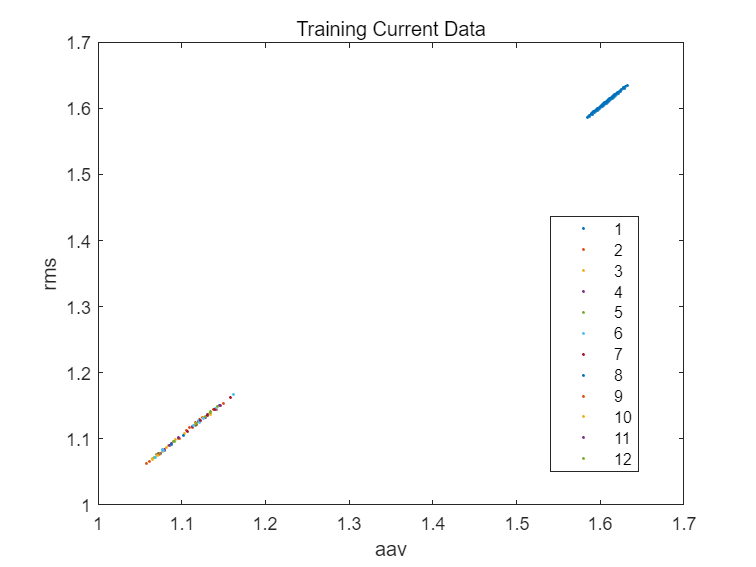

% current 와 temperature 의 feature selection을 진행한 traindata를 가지고 svm model
% 적용

% X : trainDataSelected_current Y : plc_current_feature(1:idx_train).error
X(:,1) = table2array( trainDataSelected_current(:,"aav"));
X(:,2) = table2array(trainDataSelected_current(:,"rms"));
X(:,3) = table2array(trainDataSelected_current(:,"sra"));
X(:,4) = table2array(trainDataSelected_current(:,"std"));
test_current_feature_table = struct2table(test_current_feature);
Xtest(:,1) = table2array(test_current_feature_table(:,"aav"));
Xtest(:,2) = table2array(test_current_feature_table(:,"rms"));
Xtest(:,3) = table2array(test_current_feature_table(:,"sra"));
Xtest(:,4) = table2array(test_current_feature_table(:,"std"));

Y = struct2table(train_current_feature);
Y = table2array(Y(:,"error"));
Y(:,1) = Y(:,1) + 1;
Ynew = struct2table(test_current_feature);
Ynew = table2array(Ynew(:,"error"));
Ynew(:,1) = Ynew(:,1) + 1;

figure;
gscatter(X(:, 1), X(:, 2),Y);
xlabel('aav');
ylabel('rms');
title('Training Current Data');
legend("Position",[0.72798,0.16845,0.11607,0.45119])

classLabels = categorical([1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12]);

% SVM 기반 ECOC 학습
cl = fitcecoc(X, Y, 'Learners', templateSVM('KernelFunction', 'rbf'), ...
              'ClassNames', classLabels, 'Coding', 'onevsall', 'Verbose', 1);

89개의 음성 관측값과 1072개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 1(SVM)을(를) 훈련시키는 중입니다.
1143개의 음성 관측값과 18개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 2(SVM)을(를) 훈련시키는 중입니다.
1143개의 음성 관측값과 18개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 3(SVM)을(를) 훈련시키는 중입니다.
1144개의 음성 관측값과 17개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 4(SVM)을(를) 훈련시키는 중입니다.
1150개의 음성 관측값과 11개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 5(SVM)을(를) 훈련시키는 중입니다.
1151개의 음성 관측값과 10개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 6(SVM)을(를) 훈련시키는 중입니다.
1154개의 음성 관측값과 7개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 7(SVM)을(를) 훈련시키는 중입니다.
1159개의 음성 관측값과 2개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 8(SVM)을(를) 훈련시키는 중입니다.
1159개의 음성 관측값과 2개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 9(SVM)을(를) 훈련시키는 중입니다.
1159개의 음성 관측값과 2개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 10(SVM)을(를) 훈련시키는 중입니다.
1160개의 음성 관측값과 1개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 11(SVM)을(를) 훈련시키는 중입니다.
1160개의 음성 관측값과 1개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 12(SVM)을(를) 훈련시키는 중입니다.


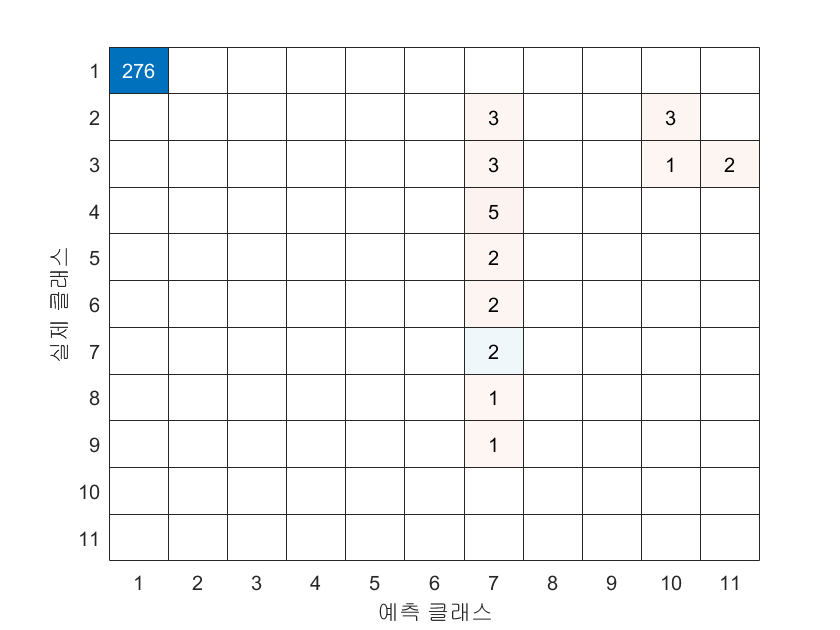

mlClass = predict(cl,Xtest);
mlClass_double = double(string(mlClass));
figure
ldaResubCM = confusionchart(Ynew,mlClass_double);

# Validation

# Fault Monitoring and Warning

# RUL Estimation

# Discussion

# Conclusion

**Functions**

function xfeature = get_features(x)
% This is based on the function timeFeatures() 
% Input: Raw Data (Time-series)
% Output: Struct type
% |
% |---Time features(e.g. RMS, peak2peak, kurtosis)
% |---Frequency features(e.g. FFT, rmsf)
N = length(x);
xfeature.mean=mean(x);
xfeature.std=std(x);

xfeature.rms      =sqrt(sum(x.^2)/N);
xfeature.sra      =(sum(sqrt(abs(x)))/N).^2;
xfeature.aav      =sum(abs(x))/N;
xfeature.energy   =sum(x.^2);
xfeature.peak     =max(x);
xfeature.ppv      =peak2peak(x);
xfeature.if       =xfeature.peak/xfeature.aav;
xfeature.sf       =xfeature.rms/xfeature.aav;
xfeature.cf       =xfeature.peak/xfeature.rms;
xfeature.mf       =xfeature.peak/xfeature.sra;
xfeature.sk       =skewness(x);
xfeature.kt       =kurtosis(x);

p1 = fft(x);
p1(2:end-1)= 2.0 * p1(2:end-1); 
xfeature.fft = p1;
xfeature.rmsf= sqrt(1/N *sum(xfeature.fft.^2));
end

function xfeature = get_features_error(x,y)
% This is based on the function timeFeatures() 
% Input: Raw Data (Time-series)
% Output: Struct type
% |
% |---Time features(e.g. RMS, peak2peak, kurtosis)
% |---Frequency features(e.g. FFT, rmsf)
N = length(x);
N_Y= length(y);
xfeature.mean=mean(x);
xfeature.std=std(x);

xfeature.rms      =sqrt(sum(x.^2)/N);
xfeature.sra      =(sum(sqrt(abs(x)))/N).^2;
xfeature.aav      =sum(abs(x))/N;
xfeature.energy   =sum(x.^2);
xfeature.peak     =max(x);
xfeature.ppv      =peak2peak(x);
xfeature.if       =xfeature.peak/xfeature.aav;
xfeature.sf       =xfeature.rms/xfeature.aav;
xfeature.cf       =xfeature.peak/xfeature.rms;
xfeature.mf       =xfeature.peak/xfeature.sra;
xfeature.sk       =skewness(x);
xfeature.kt       =kurtosis(x);

p1 = fft(x);
p1(2:end-1)= 2.0 * p1(2:end-1); 
xfeature.fft = p1;
xfeature.rmsf= sqrt(1/N *sum(xfeature.fft.^2));

xfeature.error = sum(y)/N_Y;
end


%%

function average_feature = get_average_feature(x,feature_name)
% Input: the whole cell
    FEATURES =3;
    N = length(x);
    feature = 0.0;
    for idx= 1:N
        structure = x{idx,FEATURES};
        val =getfield(structure,feature_name);
        feature = feature + val(1);
    end
    average_feature = feature/N;
end

%%
function vectors = get_all_feature(x,feature_name)
% Input: whole cell
    FEATURES =3;
    N = length(x);
    vectors = [];
    for idx= 1:N
        structure = x{idx,FEATURES};
        val =getfield(structure,feature_name);
        vectors = [vectors; val(1)]; 
    end
end

%%
function [frequency , Amplitude] = get_fft(data,Fs)
% Input : data: Time-series data
%         Fs  : Sampling Frequency
% Output: frequency: Frequency Domain(Bound)
%         Amplitude: Corresponding amplitude of fft data to the frequency
    N = length(data);
    frequency = 0.0:Fs/N:Fs/2;
    fft_data = abs(fft(data)/N);
    fft_data = fft_data(1:floor(N/2)+1);
    fft_data(2:end-1) = 2*fft_data(2:end-1);
    Amplitude = fft_data;
end

%%
function frequency_features = get_freq_features(fft_data, Fs)
% Input  fft_data: fft amplitude data
%        Fs: sampling frequency
% Output frequency_features: table for frequency features. 
    N = length(fft_data);
    frequency_features = table;
    frequency_features.max_amplitude     = max(fft_data);
    frequency_features.frequency_of_max_amplitude = (find(fft_data == max(fft_data))-1)*Fs/N;
    frequency_features.DC_value = fft_data(1);
end
%%



## Reference

[1] (주) KEMP, *Innozinc**세라믹 아연도금**,* [http://kempkorea.com/](http://kempkorea.com/) 

[2] Rauber, Thomas W., Francisco de Assis Boldt, and Flavio Miguel Varejao. "Heterogeneous feature models and feature selection applied to bearing fault diagnosis." *IEEE Transactions on Industrial Electronics* 62.1 (2014): 637-646.

[3] Toliyat, Hamid A., et al. *Electric machines: modeling, condition monitoring, and fault diagnosis*. CRC press, 2017.

[4] 